# Simulate box's trajectory and track it 

Specifying all parameters, boh for simulation (_sim) and for the Extended Kalman Filter

%rng(1);    % For repeatable results
dt = 0.005;     % seconds
simTime = 1; % seconds
tspan   = 0:dt:simTime;

m=0.3;%Kg for the box
m_sim=0.3;%Kg
m_ee=2;%Kg for the end effector's mass, equivalent to inertia
m_ee_sim=2;
mu=0.3;%Coefficient of friction
mu_sim=0.3;
g=-9.81;%N/Kg gravity
restit = 0.7;%Restitution factor
restit_sim = 0.7;

flux = 1;%m/s, Define the flux for the hit
flux_sim=1;
V_EE = flux * (1 + (m_sim/m_ee_sim))/(1+restit_sim);%Get the end-effector speed required to achieve target flux

sigma_2=0.01; %Standard deviation
sigma_1= m*((1+restit)^2 * flux^2) / (2 * sigma_2 * sqrt(2*pi)); %Max amplitude of the Hitting force
sigma_1

sigma_1 = 17.2941


X_0 = 0;%Initial position of box
D_0 = 0.1;%Initial distance

Impulse_type = 0;%0 for impulse, 1 for gaussian

trueInitialState = [X_0; 0; 0; D_0; V_EE; 0]; % [x;vx;f;d;v_ee;fh]
processNoise = diag([0; 0; 0; 0; 0 ; 0]); % No process noise in this model, but from report : Process noise matrix diag([0.01; 0.1; 0.14; 0.01])
%measureNoise = 0.005^2; % Measurement noise matrix

numSteps = length(tspan);
trueStates = NaN(6,numSteps);
trueStates(:,1) = trueInitialState;



## Obtain True States and Measurements

Propagate the constant velocity model, and generate the measurements with noise. 

%Note that the total force transmitted through impact is equal to :
%Integral Fh over d = sigma_1 * sigma_2 * sqrt(2*pi)

% [x;vx;f;d;v_ee;fh]
A = [1  dt  ((dt^2)/(2*m))  0 0 ((dt^2)/(2*m));
     0  1   dt/m            0 0 dt/m; 
     0  0   1               0 0 0;
     0  dt  0               1 -dt 0;
     0  0   0           0 1 -dt/m_ee;
     0  0   0               0 0 0];
C = [1 0 0 0 0 0];

for i = 2:length(tspan)
    trueStates(:,i) = A*trueStates(:,i-1) + sqrt(processNoise)*randn(6,1);
    if Impulse_type == 1
        trueStates(6,i) = sigma_1 * exp(-(trueStates(4,i)^2)/(2*sigma_2^2)); %Modulate applied force by distance
    else
       if trueStates(4,i)<0
           trueStates(2,i) = (1+restit_sim) * flux_sim;%V+ = (1+restit) * flux
           trueStates(5,i) = (trueStates(2,i)*m) / (m_ee_sim^2 / trueStates(5,i));%Xe+ = m*v+ / m_ee^2*v_ee- 
       end
    end
    if abs(trueStates(2,i)) > 6e-3 %Only if speed is high enough, apply friction ; prevent osicllations around 0 speed
        trueStates(3,i) = mu_sim*g*m_sim*(trueStates(2,i)/abs(trueStates(2,i)));%f=m*g*mu*v/abs(v)
    else trueStates(3,i) = 0;
    end
end
%measurements = C*trueStates + sqrt(measureNoise)*randn(1,numSteps);

Xf = NaN(1,numSteps);
for i = 1:length(tspan)
    Xf(i) = trueStates(1,i) + (0.5 * trueStates(2,i)^2 / (mu * 9.81));
end

Plot the true trajectory

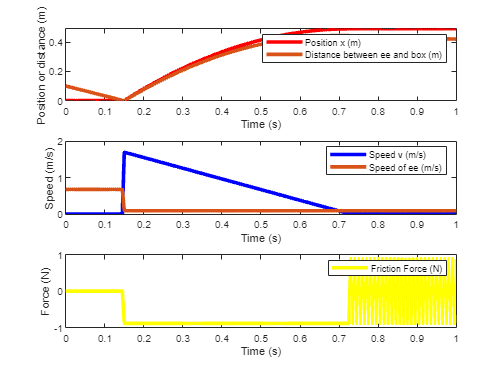

figure
subplot(3,1,1)
plot(tspan,trueStates(1,:),"r",'LineWidth',3,DisplayName="Position x (m)")
hold on
plot(tspan,trueStates(4,:),'LineWidth',3,DisplayName="Distance between ee and box (m)")
ylabel("Position or distance (m)")
xlabel("Time (s)")
legend


subplot(3,1,2)
plot(tspan,trueStates(2,:),"b",'LineWidth',3,DisplayName="Speed v (m/s)")
hold on
plot(tspan,trueStates(5,:),'LineWidth',3,DisplayName="Speed of ee (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend

subplot(3,1,3)
plot(tspan,trueStates(3,:),"y",'LineWidth',3,DisplayName="Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend

## Initialize Extended Kalman Filter

Initialize the filter

n=5;      %number of state
q=0.01;    %std of process 
r=0.005;    %std of measurement
Q=q^2*eye(n); % covariance of process
R=r^2;        % covariance of measurement  

%f=@(x)[x(1)+dt*x(2)+((dt*dt)/(2*m) * (x(3) + x(4)));
%       x(2) + (dt/m) * (x(3) + x(4));
%       -m*9.81*mu*sign(x(2));
%       sigma_1*exp(-x(5)^2 / (2*sigma_2^2));
%       x(5) + x(2)*dt];% nonlinear state equations

h=@(x)[x(1);x(5)];                        % measurement equation
s=[X_0;0;0;0;D_0];                        % initial state
x=s+q*randn(5,1); %initial state          % initial state with noise
P = eye(n);                               % initial state covariance

%numSteps = length(tspan);
%trueStates = NaN(6,numSteps); [x;vx;Ff; Fh;d]
%trueStates(:,1) = trueInitialState; 
estimateStates = NaN(5,numSteps);
Xf_pred = NaN(1,numSteps);

for k=1:numSteps
  z = trueStates([1 4],k) + r*randn;        % measurements
  [x, P] = ekf(x,P,h,z,Q,R,dt,m,mu,sigma_1,sigma_2); % ekf 
  estimateStates(:,k) = x;                % save estimate
  s = f(s,m,mu,dt,sigma_1,sigma_2) + q*randn(5,1);  % update process 
  Xf_pred(k) = x(1) + (0.5 * x(2)^2 / (mu * 9.81));
end


## Run Linear Kalman Filter and Show Results

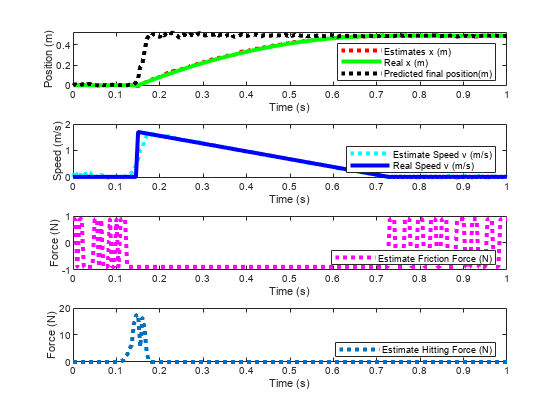

figure

subplot(4,1,1)
plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
hold on
plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final position(m)")
ylabel("Position (m)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,2)
plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
hold on
plot(tspan,trueStates(2,:),"b",'LineWidth',3,DisplayName="Real Speed v (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,3)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(3,:),":m",'LineWidth',3,DisplayName="Estimate Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,4)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(4,:),":",'LineWidth',3,DisplayName="Estimate Hitting Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

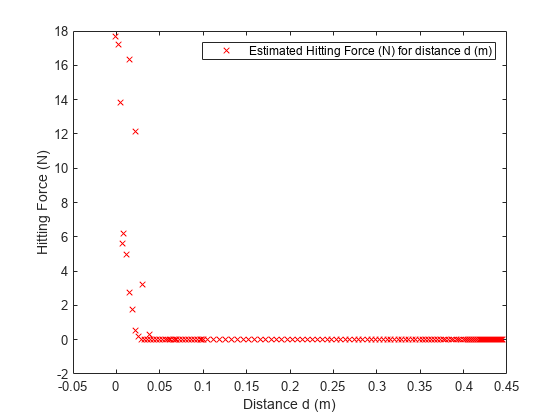

%plot(tspan,Xf,'LineWidth',3,DisplayName="Real final position (m)")

%plot(tspan,trueStates(4,:),'LineWidth',3,DisplayName="Distance between ee and box (m)")
%plot(tspan,estimateStates(5,:),'LineWidth',3,DisplayName="Estimated Distance between ee and box (m)")

figure
plot(trueStates(4,:),estimateStates(4,:),"rx",DisplayName="Estimated Hitting Force (N) for distance d (m)")
%plot(estimateStates(5,:),estimateStates(4,:),"rx",DisplayName="Estimated Hitting Force (N) for distance d (m)")
legend
xlabel("Distance d (m)")
ylabel("Hitting Force (N)")

## Use wrong estimated parameters of the Extended Kalman Filter and Show Results

%% New parameters for the EKF, different from the simulation
m=0.3;%Kg for the box
m_sim=0.3;%Kg
m_ee=2;%Kg for the end effector's mass, equivalent to inertia
m_ee_sim=2;
mu=0.1;%Coefficient of friction
mu_sim=0.3;
g=-9.81;%N/Kg gravity
restit = 0.7;%Restitution factor
restit_sim = 0.7;
flux = 1;%m/s, Define the flux for the hit
flux_sim=1;

sigma_2=0.01; %Standard deviation
sigma_1= m*((1+restit)^2 * flux^2) / (2 * sigma_2 * sqrt(2*pi)); %Max amplitude of the Hitting force
sigma_1

sigma_1 = 17.2941

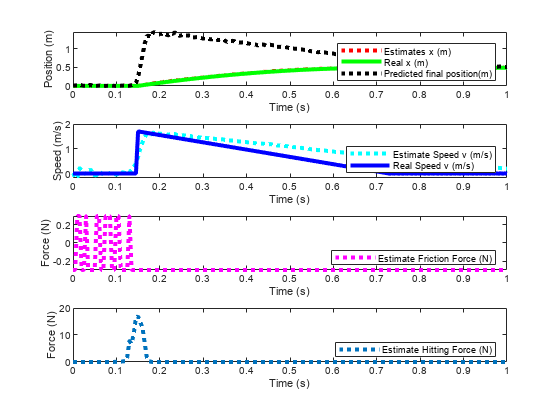


estimateStates = NaN(5,numSteps);
Xf_pred = NaN(1,numSteps);

x=s+q*randn(5,1); %initial state          % initial state with noise
P = eye(n);                               % initial state covariance

for k=1:numSteps
  z = trueStates([1 4],k) + r*randn;        % measurements
  [x, P] = ekf(x,P,h,z,Q,R,dt,m,mu,sigma_1,sigma_2); % ekf 
  estimateStates(:,k) = x;                % save estimate
  s = f(s,m,mu,dt,sigma_1,sigma_2) + q*randn(5,1);  % update process 
  Xf_pred(k) = x(1) + (0.5 * x(2)^2 / (mu * 9.81));
end

figure

subplot(4,1,1)
plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
hold on
plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final position(m)")
ylabel("Position (m)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,2)
plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
hold on
plot(tspan,trueStates(2,:),"b",'LineWidth',3,DisplayName="Real Speed v (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,3)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(3,:),":m",'LineWidth',3,DisplayName="Estimate Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,4)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(4,:),":",'LineWidth',3,DisplayName="Estimate Hitting Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

## Estimating parameters from last hit

%%Maximum estimated speed from EKF
max(estimateStates(2,10:end))

ans = 1.6495

%%Maximum speed experienced by the box
max(trueStates(2,:))

ans = 1.7000


%%Distance travelled by the box
trueStates(1,end)-trueStates(1,10)

ans = 0.4911


%%Grouping restitution factor and flux together, keeping fixed flux:
restit_est = (max(estimateStates(2,:)) / flux) - 1

restit_est = 0.6495

%%Grouping mu and mass together, keeping fixed m:
mu_est = (max(estimateStates(2,10:end))^2 / ((trueStates(1,end)-trueStates(1,10)) * 2 * 9.81))

mu_est = 0.2824

## Adjusting with newly estimated parameters

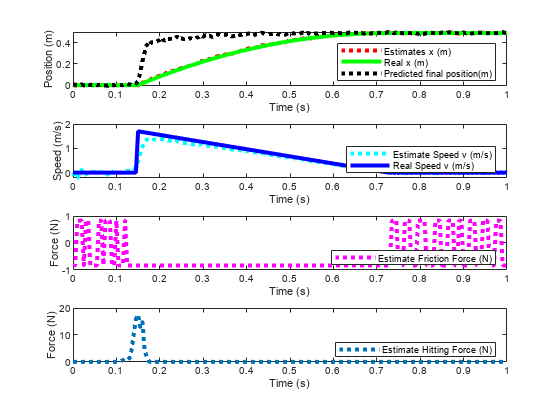

%% New parameters for the EKF, from estimates
restit = restit_est;%Restitution factor
mu = mu_est;

estimateStates = NaN(5,numSteps);
Xf_pred = NaN(1,numSteps);

x=s+q*randn(5,1); %initial state          % initial state with noise
P = eye(n);                               % initial state covariance

for k=1:numSteps
  z = trueStates([1 4],k) + r*randn;        % measurements
  [x, P] = ekf(x,P,h,z,Q,R,dt,m,mu,sigma_1,sigma_2); % ekf 
  estimateStates(:,k) = x;                % save estimate
  s = f(s,m,mu,dt,sigma_1,sigma_2) + q*randn(5,1);  % update process 
  Xf_pred(k) = x(1) + (0.5 * x(2)^2 / (mu * 9.81));
end

figure

subplot(4,1,1)
plot(tspan,estimateStates(1,:),":r",'LineWidth',3,DisplayName="Estimates x (m)")
hold on
plot(tspan,trueStates(1,:),"g",'LineWidth',3,DisplayName="Real x (m)")
plot(tspan,Xf_pred,":k",'LineWidth',3,DisplayName="Predicted final position(m)")
ylabel("Position (m)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,2)
plot(tspan,estimateStates(2,:),":c",'LineWidth',3,DisplayName="Estimate Speed v (m/s)")
hold on
plot(tspan,trueStates(2,:),"b",'LineWidth',3,DisplayName="Real Speed v (m/s)")
ylabel("Speed (m/s)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,3)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(3,:),":m",'LineWidth',3,DisplayName="Estimate Friction Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")

subplot(4,1,4)
%plot(tspan,trueStates(3,:)+trueStates(6,:),"m",'LineWidth',3,DisplayName="Real Force (N)")
plot(tspan,estimateStates(4,:),":",'LineWidth',3,DisplayName="Estimate Hitting Force (N)")
ylabel("Force (N)")
xlabel("Time (s)")
legend(Location="southeast")




%EKF Functions
% By Yi Cao at Cranfield University, 02/01/2008
%
function [x,P]=ekf(x,P,hmeas,z,Q,R,dt,m,mu,sigma_1,sigma_2)
% EKF   Extended Kalman Filter for nonlinear dynamic systems
% [x, P] = ekf(f,x,P,h,z,Q,R) returns state estimate, x and state covariance, P 
% for nonlinear dynamic system:
%           x_k+1 = f(x_k) + w_k
%           z_k   = h(x_k) + v_k
% where w ~ N(0,Q) meaning w is gaussian noise with covariance Q
%       v ~ N(0,R) meaning v is gaussian noise with covariance R
% Inputs:   f: function handle for f(x)
%           x: "a priori" state estimate
%           P: "a priori" estimated state covariance
%           h: fanction handle for h(x)
%           z: current measurement
%           Q: process noise covariance 
%           R: measurement noise covariance
% Output:   x: "a posteriori" state estimate
%           P: "a posteriori" state covariance
%

[x1,A]=jaccsd(x,dt,m,mu,sigma_1,sigma_2);    %nonlinear update and linearization at current state
P=A*P*A'+Q;                 %partial update
H = [1 0 0 0 0;
     0 0 0 0 1];
z1 = [x(1); x(5)];          %Observation
P12=P*H';                   %cross covariance
% K=P12*inv(H*P12+R);       %Kalman filter gain
% x=x1+K*(z-z1);            %state estimate
% P=P-K*P12';               %state covariance matrix
R=chol(H*P12+R);            %Cholesky factorization
U=P12/R;                    %K=U/R'; Faster because of back substitution
x=x1+U*(R'\(z-z1));         %Back substitution to get state update
P=P-U*U';                   %Covariance update, U*U'=P12/R/R'*P12'=K*P12.
end

function [z,A]=jaccsd(x,dt,m,mu,sigma_1,sigma_2)
% JACCSD Jacobian through complex step differentiation
% [z J] = jaccsd(f,x)
% z = f(x)
% J = f'(x)
%
z=f(x,m,mu,dt,sigma_1,sigma_2);
A=[1 dt (dt^2)/(2*m) (dt^2)/(2*m) 0;
   0 1 dt/m dt/m 0;
   0 0 0 0 0;
   0 0 0 0 -sigma_1*abs(x(5)/sigma_2^2) * exp(-x(5)^2 / (2*sigma_2^2)); %-sigma_1*abs(x(5)/sigma_2^2) * exp(-x(5)^2 / (2*sigma_2^2))
   0 0 0 0 1]; 
end

function y=f(x,m,mu,dt,sigma_1,sigma_2)
y = [x(1)+dt*x(2)+((dt*dt)/(2*m) * (x(3) + x(4))); % x(1)+dt*x(2)+((dt*dt)/(2*m) * (x(3) + x(4)));
     x(2) + (dt/m) * (x(3) + x(4));
     -m*9.81*mu*sign(x(2));
     sigma_1*exp(-x(5)^2 / (2*sigma_2^2));
     x(5)];% nonlinear state equations

%if (abs(x(2)) <= 1e-2) | (x(5) < 3*sigma_2) %Only if speed is high enough and d latge enough, apply friction ; prevent osicllations around 0 speed
%        y(3) = 0;
%end
end

*Copyright 2021 The MathWorks, Inc.*